# `Author: Ambika Prasad Dahal`

# `Kinematics`

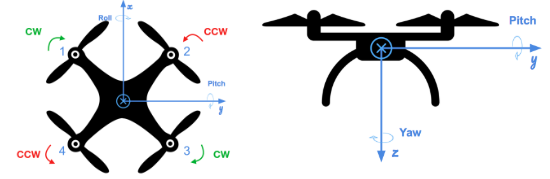

`Let "N" be the Newtonian Frame. We are going to assume a Roll-Pitch-Yaw Euler Sequence. First, the body will Roll around X-axis of some intermediate frame (B2) with angle phi (`$\left.\phi \right)$.`Then, the body will Pitch around Y-axis of another intermediate frame (B1) with angle theta (`$\left.\theta \right)$. `Finally, the body will Yaw around Z-axis of the Body Frame (B) with angle psi (`$\left.\psi \right)$.

## Defining Rotations and Forumulating Rotation Matrix for Body to Newtonian Transformation.

% Defining some symbols
syms phi theta psi

% Defining Rotation around x-axis (Roll) of B2 Frame.
NtoB2 = [1 0 0; 0 cos(phi) -sin(phi); 0 sin(phi) cos(phi)]

$$NtoB2 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\phi \right) & -\sin\left(\phi \right)\\ 0 & \sin\left(\phi \right) & \cos\left(\phi \right) \end{array}\right)$$

% Defining Rotation around y-axis (Pitch) of B1 Frame.
B2toB1 = [cos(theta) 0 sin(theta); 0 1 0; -sin(theta) 0 cos(theta)]

$$B2toB1 = \left(\begin{array}{ccc} \cos\left(\theta \right) & 0 & \sin\left(\theta \right)\\ 0 & 1 & 0\\ -\sin\left(\theta \right) & 0 & \cos\left(\theta \right) \end{array}\right)$$

% Defining Rotation around z-axis (Yaw) of B Frame.
B1toB = [cos(psi) -sin(psi) 0; sin(psi) cos(psi) 0; 0 0 1]

$$B1toB = \left(\begin{array}{ccc} \cos\left(\psi \right) & -\sin\left(\psi \right) & 0\\ \sin\left(\psi \right) & \cos\left(\psi \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

% To transform from Body Frame B to Newtonian Frame N, we need Rotation Matrix (NtoB).
NtoB = B1toB * B2toB1 * NtoB2 % yaw * pitch *roll

$$NtoB = \left(\begin{array}{ccc} \cos\left(\psi \right)\,\cos\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\phi \right)\,\sin\left(\theta \right)-\cos\left(\phi \right)\,\sin\left(\psi \right) & \sin\left(\phi \right)\,\sin\left(\psi \right)+\cos\left(\phi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\\ \cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\phi \right)\,\cos\left(\psi \right)+\sin\left(\phi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\phi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\phi \right)\\ -\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\phi \right) & \cos\left(\phi \right)\,\cos\left(\theta \right) \end{array}\right)$$

## `Formulating the Rate of Change of Euler Angles from the Body Angular Velocities.`

`phi_dot, theta_dot, psi_dot are Euler Rates.`

`p,q,r are Body Rates.`

syms phi_dot theta_dot psi_dot p q r
Eul_dot = [p;q;r] == NtoB2*B2toB1*[0;0;psi_dot]+ NtoB2 * [0; theta_dot; 0]+ [phi_dot;0;0];
expand(Eul_dot)

$$ans = \left(\begin{array}{c} p=\phi_{\mathrm{dot}}+\psi_{\mathrm{dot}}\,\sin\left(\theta \right)\\ q=\theta_{\mathrm{dot}}\,\cos\left(\phi \right)-\psi_{\mathrm{dot}}\,\cos\left(\theta \right)\,\sin\left(\phi \right)\\ r=\theta_{\mathrm{dot}}\,\sin\left(\phi \right)+\psi_{\mathrm{dot}}\,\cos\left(\phi \right)\,\cos\left(\theta \right) \end{array}\right)$$

`Clearly there is a transformation matrix such that Euler_Rates = Body2Euler_Rates * Body_Rates.`

Euler2Body_Rates=[1 0 sin(theta);0 cos(phi) -cos(theta)*sin(phi); 0 sin(phi) cos(phi)*cos(theta)];

Test if we can get same R.H.S. equations as above.

Body_Rates=Euler2Body_Rates*[phi_dot;theta_dot;psi_dot]

$$Body\_Rates = \left(\begin{array}{c} \phi_{\mathrm{dot}}+\psi_{\mathrm{dot}}\,\sin\left(\theta \right)\\ \theta_{\mathrm{dot}}\,\cos\left(\phi \right)-\psi_{\mathrm{dot}}\,\cos\left(\theta \right)\,\sin\left(\phi \right)\\ \theta_{\mathrm{dot}}\,\sin\left(\phi \right)+\psi_{\mathrm{dot}}\,\cos\left(\phi \right)\,\cos\left(\theta \right) \end{array}\right)$$

Body2Euler_Rates=simplify(inv(Euler2Body_Rates))

$$Body2Euler\_Rates = \left(\begin{array}{ccc} 1 & \frac{\sin\left(\phi \right)\,\sin\left(\theta \right)}{\cos\left(\theta \right)} & -\frac{\cos\left(\phi \right)\,\sin\left(\theta \right)}{\cos\left(\theta \right)}\\ 0 & \cos\left(\phi \right) & \sin\left(\phi \right)\\ 0 & -\frac{\sin\left(\phi \right)}{\cos\left(\theta \right)} & \frac{\cos\left(\phi \right)}{\cos\left(\theta \right)} \end{array}\right)$$

# `Dynamics`

`Forces`

`The Forces produced by Propellers always act alongs z-axis of Body Frame (B). So, the net thrust on the body is the summation of thrusts produced by individual propellers.`

syms kf omega1 omega2 omega3 omega4
F1 = kf*omega1^2

$$F1 = \mathrm{kf}\,{\omega_{1}}^{2}$$

F2 = kf*omega2^2

$$F2 = \mathrm{kf}\,{\omega_{2}}^{2}$$

F3 = kf*omega3^2

$$F3 = \mathrm{kf}\,{\omega_{3}}^{2}$$

F4 = kf*omega4^2

$$F4 = \mathrm{kf}\,{\omega_{4}}^{2}$$

Fx_body = 0;
Fy_body = 0;
Fz_body = (F1+F2+F3+F4); % Total Thrust on Drone as seen from Body Frame.
F_Body = [Fx_body; Fy_body; -Fz_body]

$$F\_Body = \left(\begin{array}{c} 0\\ 0\\ -\mathrm{kf}\,{\omega_{1}}^{2}-\mathrm{kf}\,{\omega_{2}}^{2}-\mathrm{kf}\,{\omega_{3}}^{2}-\mathrm{kf}\,{\omega_{4}}^{2} \end{array}\right)$$

`The gravity vector "g" is always pointing downwards (i.e. along z-axis of Newtonian Frame) and Fz_body points upward (-ve z-axis of Body Frame according to our schematic).`

`Linear Accelerations as seen from Newtonian Frame Derived From Forces as seen from Newtonian Frame.`

`From Newton's Equations, Fnet = m*acceleration.`

`We need to transform "acceleration seen from Body Frame" to "acceleration seen from Newtonian Frame".`

syms g m x_ddot y_ddot z_ddot
accl_body = (F_Body)/m

$$accl\_body = \left(\begin{array}{c} 0\\ 0\\ -\frac{\mathrm{kf}\,{\omega_{1}}^{2}+\mathrm{kf}\,{\omega_{2}}^{2}+\mathrm{kf}\,{\omega_{3}}^{2}+\mathrm{kf}\,{\omega_{4}}^{2}}{m} \end{array}\right)$$

linacc_Newtonian = [x_ddot;y_ddot;z_ddot] == NtoB * accl_body + [0;0;g];
linacc_sol = solve(linacc_Newtonian,[x_ddot,y_ddot,z_ddot]);
x_ddot = linacc_sol.x_ddot

$$x\_ddot = -\frac{\left(\sin\left(\phi \right)\,\sin\left(\psi \right)+\cos\left(\phi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\right)\,\left(\mathrm{kf}\,{\omega_{1}}^{2}+\mathrm{kf}\,{\omega_{2}}^{2}+\mathrm{kf}\,{\omega_{3}}^{2}+\mathrm{kf}\,{\omega_{4}}^{2}\right)}{m}$$

y_ddot = linacc_sol.y_ddot

$$y\_ddot = \frac{\left(\cos\left(\psi \right)\,\sin\left(\phi \right)-\cos\left(\phi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)\right)\,\left(\mathrm{kf}\,{\omega_{1}}^{2}+\mathrm{kf}\,{\omega_{2}}^{2}+\mathrm{kf}\,{\omega_{3}}^{2}+\mathrm{kf}\,{\omega_{4}}^{2}\right)}{m}$$

z_ddot = linacc_sol.z_ddot

$$z\_ddot = g-\frac{\cos\left(\phi \right)\,\cos\left(\theta \right)\,\left(\mathrm{kf}\,{\omega_{1}}^{2}+\mathrm{kf}\,{\omega_{2}}^{2}+\mathrm{kf}\,{\omega_{3}}^{2}+\mathrm{kf}\,{\omega_{4}}^{2}\right)}{m}$$

`Torques/Moments on Body`

`Note: Propeller 1 and 3 rotate clockwise producing counterclockwise reaction moment on body. Similarly, Propeller 2 and 4 rotate counterclockwise producing clockwise reaction moment on body.`

`Let 'L' be rotor to rotor distance and 'l' be the perpendicular distances from axes to the rotors.`

`The moments around x and y axes are generated by Thrust.`

`The moment around z axis is generated by rotational speed of propellers. `

syms L l km
l = L/(2*sqrt(2)); % l^2 + l^2 = (L/2)^2
T1 = -km*omega1^2; 
T2 = km*omega2^2; 
T3 = -km*omega3^2;
T4 = km*omega4^2;
% Moment Generation around x,y,z-axes of body
M_x = (F1+F4-F2-F3)*l

$$M\_x = \frac{\sqrt{2}\,L\,\left(\mathrm{kf}\,{\omega_{1}}^{2}-\mathrm{kf}\,{\omega_{2}}^{2}-\mathrm{kf}\,{\omega_{3}}^{2}+\mathrm{kf}\,{\omega_{4}}^{2}\right)}{4}$$

M_y = (F1+F2-F3-F4)*l

$$M\_y = \frac{\sqrt{2}\,L\,\left(\mathrm{kf}\,{\omega_{1}}^{2}+\mathrm{kf}\,{\omega_{2}}^{2}-\mathrm{kf}\,{\omega_{3}}^{2}-\mathrm{kf}\,{\omega_{4}}^{2}\right)}{4}$$

M_z = T1 + T2 + T3 + T4

$$M\_z = -\mathrm{km}\,{\omega_{1}}^{2}+\mathrm{km}\,{\omega_{2}}^{2}-\mathrm{km}\,{\omega_{3}}^{2}+\mathrm{km}\,{\omega_{4}}^{2}$$

## `Setting the propeller Angular velocities`

`Based on the Inputs from the controller, we set up angular velocities of propellers. To do so, we derive following linear equations from vertical acceleration (g_ddot), roll(M_x), pitch(M_y), and yaw (M_z) equations.`

syms c_bar p_bar q_bar r_bar Ix Iy Iz 
set_omegaEqn = [c_bar; p_bar; q_bar; r_bar]== [1 1 1 1; 1 -1 -1 1; 1 1 -1 -1; 1 -1 1 -1]*[omega1^2; omega2^2; omega3^2; omega4^2]

$$set\_omegaEqn = \left(\begin{array}{c} c_{\mathrm{bar}}={\omega_{1}}^{2}+{\omega_{2}}^{2}+{\omega_{3}}^{2}+{\omega_{4}}^{2}\\ p_{\mathrm{bar}}={\omega_{1}}^{2}-{\omega_{2}}^{2}-{\omega_{3}}^{2}+{\omega_{4}}^{2}\\ q_{\mathrm{bar}}={\omega_{1}}^{2}+{\omega_{2}}^{2}-{\omega_{3}}^{2}-{\omega_{4}}^{2}\\ r_{\mathrm{bar}}={\omega_{1}}^{2}-{\omega_{2}}^{2}+{\omega_{3}}^{2}-{\omega_{4}}^{2} \end{array}\right)$$

The above Dimensionless Forms are derived as follow;

c_bar = simplify(Fz_body/kf)

$$c\_bar = {\omega_{1}}^{2}+{\omega_{2}}^{2}+{\omega_{3}}^{2}+{\omega_{4}}^{2}$$

p_bar = simplify(Ix*(M_x/Ix)/(kf*l))

$$p\_bar = {\omega_{1}}^{2}-{\omega_{2}}^{2}-{\omega_{3}}^{2}+{\omega_{4}}^{2}$$

q_bar = simplify(Iy*(M_y/Iy)/(kf*l))

$$q\_bar = {\omega_{1}}^{2}+{\omega_{2}}^{2}-{\omega_{3}}^{2}-{\omega_{4}}^{2}$$

r_bar = simplify(Iz*(M_z/Iz)/(km))

$$r\_bar = -{\omega_{1}}^{2}+{\omega_{2}}^{2}-{\omega_{3}}^{2}+{\omega_{4}}^{2}$$

## `Deriving rates of p,q,r using Euler's Rotational Equation`

`M ``= ``I ``omega_dot + omega x (``I ``omega)`

syms p_dot q_dot r_dot
eqn1 = M_x == Ix*p_dot + (Iz-Iy)*q*r;
eqn2 = M_y == Iy*q_dot + (Ix-Iz)*p*r;
eqn3 = M_z == Iz*r_dot + (Iy-Ix)*q*p;
p_dot = solve(eqn1,p_dot)

$$p\_dot = \frac{q\,r\,\left(\mathrm{Iy}-\mathrm{Iz}\right)+\frac{\sqrt{2}\,L\,\left(\mathrm{kf}\,{\omega_{1}}^{2}-\mathrm{kf}\,{\omega_{2}}^{2}-\mathrm{kf}\,{\omega_{3}}^{2}+\mathrm{kf}\,{\omega_{4}}^{2}\right)}{4}}{\mathrm{Ix}}$$

q_dot = solve(eqn2,q_dot)

$$q\_dot = -\frac{p\,r\,\left(\mathrm{Ix}-\mathrm{Iz}\right)-\frac{\sqrt{2}\,L\,\left(\mathrm{kf}\,{\omega_{1}}^{2}+\mathrm{kf}\,{\omega_{2}}^{2}-\mathrm{kf}\,{\omega_{3}}^{2}-\mathrm{kf}\,{\omega_{4}}^{2}\right)}{4}}{\mathrm{Iy}}$$

r_dot = solve(eqn3,r_dot)

$$r\_dot = \frac{-\mathrm{km}\,{\omega_{1}}^{2}+\mathrm{km}\,{\omega_{2}}^{2}-\mathrm{km}\,{\omega_{3}}^{2}+\mathrm{km}\,{\omega_{4}}^{2}+p\,q\,\left(\mathrm{Ix}-\mathrm{Iy}\right)}{\mathrm{Iz}}$$